clc; clear; close all;

% Load test data
load("currentStepTest.mat");

% Creating varible of the measured current and adding a zero offset
yData = currentStepTest(1).Current(201:218) +0.074; % Current

% Creating varible for the test time steps
xData = currentStepTest(1).time(201:218);
% And subtracting to set the first time element to zero
xData = xData - xData(1);

% Arbitrary intial guess for the time constant
tau0 = .001;

% Find optimal time constat with least square
tau = lsqcurvefit(@currentFun, tau0, xData, yData)


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


tau = 0.0125

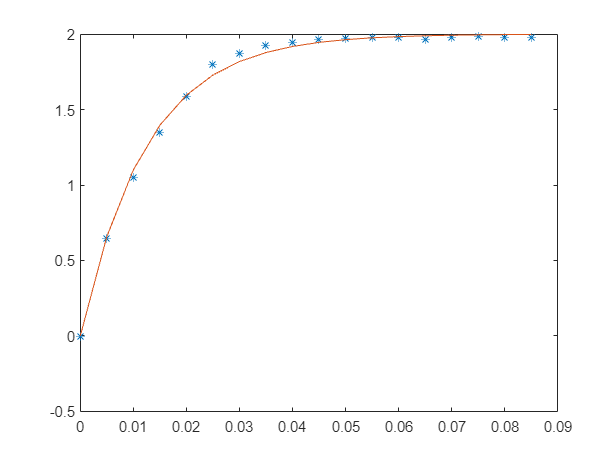


% Testing with the optimal time constant
yDataOptimal = currentFun(tau, xData);



plot(xData, yData, '*')
hold on
plot(xData, yDataOptimal)
hold off

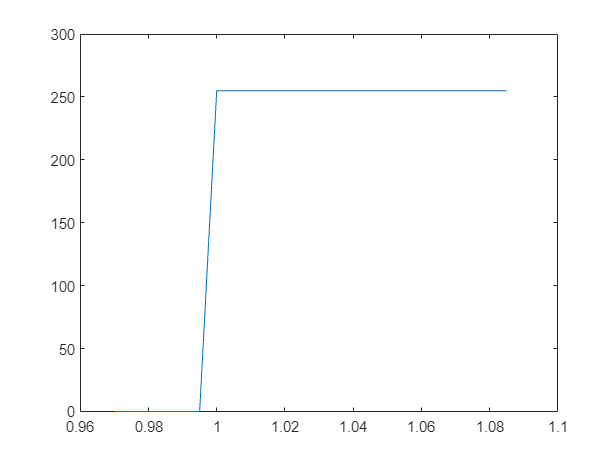




plot(currentStepTest(1).time(195:218), currentStepTest(1).PWM(195:218))

Plotting paramters 

W_frame = 16;     % Final width of the frame [cm] of the plot in your document
H_frame = 8;      % Final height of the frame [cm] of the plot in your document
LLC_frame = [5,5];% Position of lower left corner of the frame on the screen [cm]
W_axis = 14.5;    % Width of axis [cm]
H_axis = 6.7;     % Height of axis [cm]
LLC_axis = [1.25, 1.1]; % Position of lower left corner of the axes on the frame [cm]
xlabel_x = W_axis/2;% x-position of the x-label
xlabel_y = -0.6;  % y-position of the x-label [cm]
ylabel_x = -0.6;  % x-position of the y-label [cm]
ylabel_y = H_axis/2;% y-position of the y-label
AxisFontSize = 11;% Font size for axis text in the final plot in your document
LW1 = 1;          % Line width of lines on plot
LW2 = 2;          % Line width of lines on plot

Plotting for the report pendulum swing-up

fig = figure;           % Handle for the figure
ax = gca;               % Handle for the axis

%Data Point Formatting
fig.Units = 'centimeters';
fig.Position = [LLC_frame W_frame H_frame];
% Specifying the position of the lower left corner + the width and height of the frame

hold on
plt1 = plot(xData, yData, '*');
plt1.Color = 'b';    % y, m, c, r, g, b, w, k,
%plt1.LineStyle ='-';% '-', '--', ':', '-.'
%plt1.LineStyleMode = "manual"
plt1.LineWidth  = LW2;

plt2 = plot(xData, yDataOptimal);
plt2.Color = 'r';
plt2.LineStyle = '-';


ax.Units = 'centimeters';
ax.GridLineStyle = '--';                % '-' '--' ':' '-.'
ax.Position = [LLC_axis W_axis H_axis];
ax.FontName = 'Times New Roman';
ax.FontSize = AxisFontSize;             % Specified above
ax.XTick = [0:0.01:0.1];                    % Divisions on axes
ax.YTick = [-5:.5:5];                    % Divisions on axes
%axis([tmin, tmax, -5, 5]);              % lower and upper limit
%Axis Labels and Legend
label_x = xlabel('Time, [s]');
label_x.Units = "centimeters";
label_x.Position = [xlabel_x, xlabel_y];

label_y = ylabel('Current [A]');
label_y.Units = "centimeters";
label_y.Position = [ylabel_x, ylabel_y];

yaxis([-0.5 2.5]);

%leg = legend('Test data', 'i = k*U*(1-exp(1/tau*t)) ');
%leg = legend('Test data', '$i(t) = k \cdot U(t) \cdot (1-e^{-\frac{1}{\tau}t})$','Interpreter','latex')
leg = legend('Test data', 'Solution with optimal time constant')

leg =   Legend (Test data, Solution with optimal time constant) with properties:

         String: {'Test data'  'Solution with optimal time constant'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9.9000
       Position: [0.5354 0.8217 0.4305 0.1198]
          Units: 'normalized'

  Show all properties


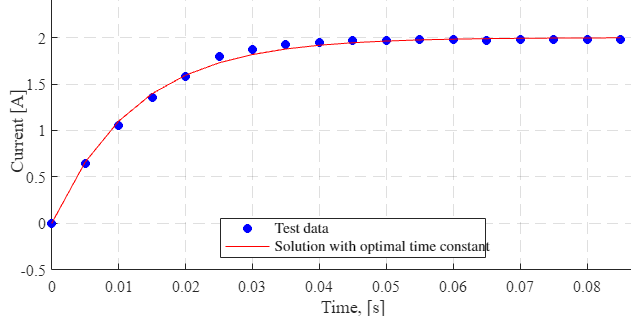


leg.Location = "south";
hold off
grid on
box on

function current = currentFun(tau, xData)
U = 10; % Volt
R = 5; % Ohm
k = 1/R; % gain
current = U*k*(1-exp(-(1)/(tau)*xData));
end